num_cyl=4;
num_s=4;
rpmupperbound=10000;

tlr=0.5;
%%sensitivity to frequency local maxes 
%(used by fft_bullet to find engine frequency)

N=10; %duration of recording in seconds

Engine Frequency (Hz) = 


fs=44100;
NFFT=2^18; %high enough resolution for fft that works decently fast

framelength=fs/4;%one audio frame= 0.25 sec

%choses how many values of the fft are used in the calculations based on rpm upper bound
hz_len=NFFT/fs*rpmupperbound*num_cyl/60*(2/num_s);
audioreader = audioDeviceReader(fs,framelength);

rpmbox=zeros(1,N*4+1);
clipbox=[];
current_chunk=zeros(1,2*framelength);
clipa=audioreader();
clipbox(1:framelength)=clipa; %preloads one frame

for i=1:N*4+1
    clip1=audioreader();%reads in a frame
    clipbox((i+1)*framelength+1:((i+2)*framelength))=clip1;
    current_chunk=clipbox((i-1)*framelength+1:((i+1)*framelength));
    engine_freq=fft_bulletV2(current_chunk,tlr,hz_len,NFFT); %processes previous 2 frames 
    rpm1=engine_freq*(num_s/2)*(1/num_cyl)*60;%converts to rpm using equation in documentation

    if isnan(rpm1) %displays engine rpms
        fprintf('NaN')
        fprintf(' ')
    else
        rpm1=round(rpm1,0);
        fprintf(string(rpm1))
        fprintf(' ')
    end
    

    if rpm1<rpmupperbound
        rpmbox(i)=rpm1;
    else
        rpmbox(i)=NaN;
    end
end

NaN

NaN

NaN

NaN

NaN

NaN

NaN

NaN

NaN

NaN

NaN

NaN

NaN

NaN

3553

NaN

NaN

NaN

NaN

NaN

NaN

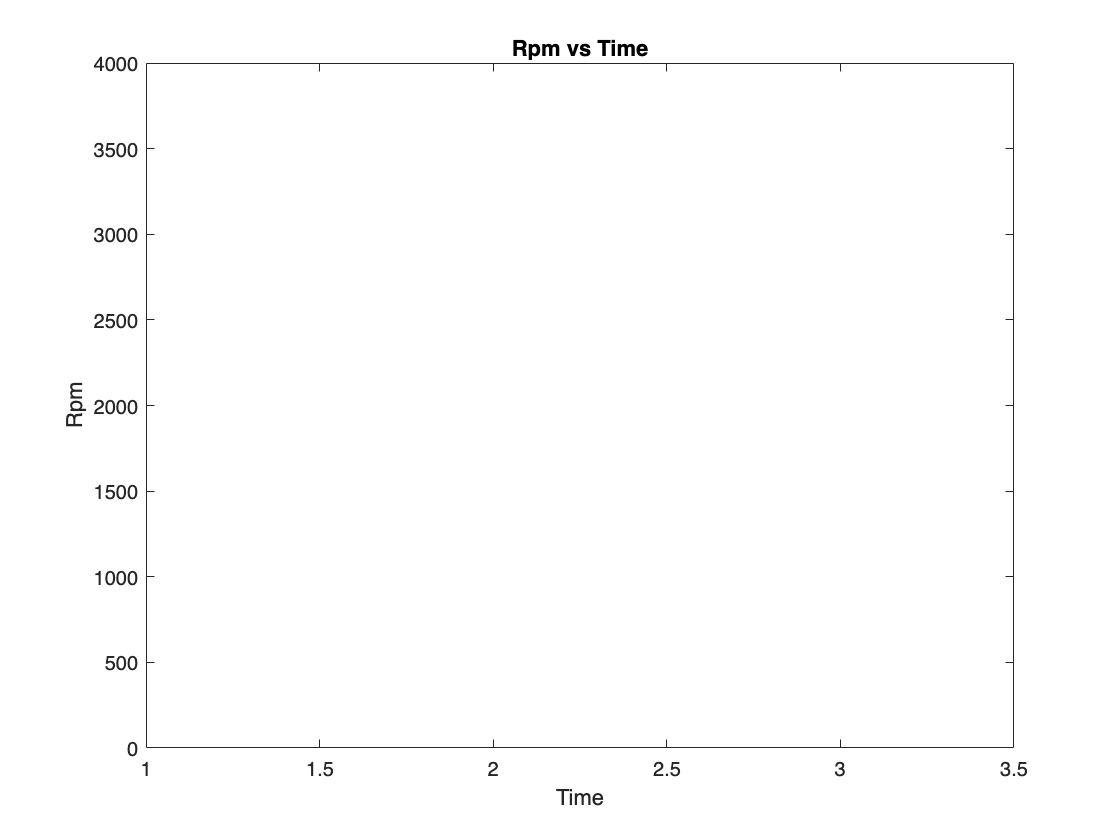

timex=linspace(0,N,N*4+1);
plot(0)
hold on
plot(timex,rpmbox)

title("Rpm vs Time")
xlabel("Time")
ylabel("Rpm")

function engine_freq=fft_bulletV2(clip1,peak_tlr,hz_len,NFFT)
    fs=44100;
    L=numel(clip1);
    alpha=5;
    tol=peak_tlr;

    %not using windowing for speed 
    % (spectral leekage should not affect calculation of local max)         
    FFT = fft(clip1(:).*gausswin(L,alpha),NFFT);

   

    %uses rpm upper bounds to find range of 
    % corresponding values in clean_fft 
    % which cuts down on computations required
    search_range=(1:hz_len);

    clean_fft=abs(FFT(search_range));

    %cuts off bottom x percent of data 
    % based on how loud the max value in the search range is
    clean_fft=clean_fft/max(clean_fft);

    ix=islocalmax(clean_fft,'MinProminence',tol);
    
    %makes sure local maxes and within range are empty for mutliple runs of matlab
    local_mxs=[];%can't preallocate because this changes every loop
    potential_max_indicies=[];

    %indicies of local maxes
    local_mxs=find(ix);%also changes every loop

    %if no local maxes
    if isempty(local_mxs)
        engine_freq=NaN;
    %if one local max
    elseif numel(local_mxs)==1
        %multiplying by fs/NFFT converts the x positions in clean_fft to Hz
        engine_freq=(local_mxs(1))*fs/NFFT;

    %if more than one local max
    else
        for i=2:numel(local_mxs)
            potential_max_indicies(1)=1;
            %scans for largest local maxes within 140% of first  
            % local max detected (see documentation for explaination)
            if (local_mxs(i))<(1.4*local_mxs(1)) 
                potential_max_indicies(i)=1;
            else
                potential_max_indicies(i)=0;
            end
        end
        %picks largest local max within 140 pct (largest range I found no
        %harmonics in
        [~,ixe]=max(clean_fft(local_mxs(potential_max_indicies>0)));
        engine_freq=local_mxs(ixe)*fs/NFFT;
    end
end